# Assignment 03 - A.A. 2023/24

close all
clear
clc

## 0) Data

Loading data and plotting time histories

% Loading data
load('Data')
t=Data(:,1);
F=Data(:,2);
x=Data(:,3:end);    % displacements in the 4 columns
np=size(x,1);        % number of samples
nj=size(x,2);        % number of displacements

dt=t(2)-t(1);        % acquisition period
fsamp=1/dt;            % sampling frequency
disp(' ')
disp(['Number of sensors: ' num2str(nj)])
disp(['dt [s]: ' num2str(dt)])
disp(['np [-]: ' num2str(np)])

% Plots
figure()
sgtitle("Measurements");

subplot(5, 1, 1);
plot(t, F)
grid on;
title("Force F(t)");
ylabel("[N]");
xlabel("[s]");
xlim([0, 0.02]);

subplot(5, 1, 2);
plot(t, x(:, 1))
grid on;
title("Displacement x_1(t)");
ylabel("[m]");
xlabel("[s]");
xlim([0, 20]);

subplot(5, 1, 3);
plot(t, x(:, 2))
grid on;
title("Displacement x_2(t)");
ylabel("[m]");
xlabel("[s]");
xlim([0, 20]);

subplot(5, 1, 4);
plot(t, x(:, 3))
grid on;
title("Displacement x_3(t)");
ylabel("[m]");
xlabel("[s]");
xlim([0, 20]);

subplot(5, 1, 5);
plot(t, x(:, 4))
grid on;
title("Displacement x_4(t)");
ylabel("[m]");
xlabel("[s]");
xlim([0, 20]);

## 1) Experimental FRF

Plot the "experimental" FRF diagrams.

% Force and displacements spectra
[x_fft, frq] = ffg(x, np, dt);
[F_fft, frq] = ffg(F, np, dt);

% Experimental FRFs = ratio output/input
Hjk_exp = x_fft./F_fft;

% Plots
figure()
sgtitle("Experimental FRFs")
for i=1:nj
    % Plotting the amplitude
    subplot(2,4,i);
    plot(frq, abs(Hjk_exp(:, i)));
    grid on;
    title("|H_"+num2str(i)+"_,_k(f)|");
    ylabel("Amplitude [m/N]");
    xlabel("Frequency [Hz]");
    xlim([0, 5]);
    
    % Plotting the amplitude
    subplot(2,4,nj+i)
    plot(frq, angle(Hjk_exp(:, i)))
    grid on;
    title("\angleH_"+num2str(i)+"_,_k(f)");
    ylabel("Angle [rad]");
    xlabel("Frequency [Hz]");
    yticks([-pi, -pi/2, 0, pi/2, pi]);
    yticklabels(["-\pi", "-\pi/2", "0", "\pi/2", "\pi"]);
    xlim([0, 5]);
end

## 2) Parameters estimation - simplified method

Estimate the natural frequencies, damping ratios and mode shapes of the resonating modes in the range $0-5\;\textrm{Hz}$ employing simplified methods (e.g. half power point method). Comment the obtained results.

%{
fini = [0, 1.3, 2.4, 3];        % Lower f in band
ffin = [1.3, 2.4, 3, 5];        % Higher f in band

res = zeros(3,16);
resonance_freqs = zeros(16,1);
h = zeros(16,1); 
for jj = 1:4        % for each FRF
    for i = 1:4        % for each mode
        % Indexes indentification
        iini = min(find(round(frq*1000)/1000 >= fini(i)));
        ifin = max(find(round(frq*1000)/1000 <= ffin(i)));
        disp('Frequency range')
        disp(['- fmin [Hz]: ' num2str(frq(iini))])
        disp(['- fmax [Hz]: ' num2str(frq(ifin))]) 
        
        % Count of points for identification
        npid = ifin - iini + 1;
        disp(['Number of points for the identification: ' num2str(npid)])
        
        % FRF evaluated in [fini, ffin]
        rfHjki = frq(iini:ifin);
        Hjkiexp = Hjk_exp(iini:ifin,:);
        
        % First guess of parameters: SIMPLIFIED METHODS
        
        % Natural frequency
        [vmax, iwmax] = max(abs(Hjkiexp(:, jj)));        % Maximum of |FRF| inside [fini, ffin]

        f0i = rfHjki(iwmax);        % Frequency [Hz] of the maximum
        w0i0 = 2*pi*f0i;            % Resonance frequency [rad/s]
        
        % Adimensional damping ration (phase derivative)
        derFIjki = (angle(Hjkiexp(iwmax+1, jj)) - angle(Hjkiexp(iwmax-1, jj)))/(2*pi*(rfHjki(iwmax+1) - rfHjki(iwmax-1)));
        hii0 = -1/(w0i0*derFIjki);        % Guessing h
        r0i = 2*w0i0*hii0;        % c/m
        
        % Mode shapes
        Aj0 = -imag(Hjkiexp(iwmax, jj))*w0i0*r0i; 
        % all the other constants are set equal to 0 (m_q = 1)
        
        resonance_freqs (i) = f0i;
        h(i) = hii0;


        % Results
        disp(' ')
        disp(['Initial guess f_0 [Hz]: ' num2str(f0i)])
        disp(['Initial guess h [-]:    ' num2str(hii0)])
        disp(['Initial guess A_0 [m]: ' num2str(Aj0)])
        

## 3) Residual minimization

Set up a modal parameter identification program, exploiting the residual minimization technique, for estimating natural frequencies, damping ratios and modes in the range $0-5\;\textrm{Hz}$. Compare the identified FRF with the “experimental” ones. Comment the obtained results.


        % Filling of vector xpar
        xpar0 = [hii0; w0i0; Aj0; zeros(5,1)];    % Unknowns: 2 mod parameters + 6 constants
        % for the initial guess of the optimization
        
        % Identification: single channel    
        options = optimset('fminsearch');
        options = optimset(options,'TolFun',1e-8,'TolX',1e-8);
        xpar = fminsearch(@(xpar) errHjki_cw(xpar, rfHjki, Hjkiexp(:, jj)), xpar0, options);

        
        % @(xpar) parameter set we're trying to find
        % Error function (difference between experimental and optimized FRF)
        
        % Plot results of identification
        vpar = [1;    2*xpar(1)*xpar(2);    xpar(2)^2;    xpar(3:8)]
        %      [m;    c = 2 m w0 csi;       k = w0^2 m;  A;B;C;D;E;F]

        disp("Modal parameters after minimization: mq"+num2str(i)+num2str(i)+ " = " +num2str(vpar(1))+ "; kq"+num2str(i)+num2str(i)+ " = " + num2str(vpar(2)) + "; cq" +num2str(i)+num2str(i)+ " = " + num2str(vpar(3)) );


        %Extracting the modal parameters
        % Each 4 consecutives columns of res contain the modal parameters
        % of the same mode of vibration but for a different measurement
        % point
        res(:, jj + 4*(i-1)) = vpar(1:3);
        
        Hjkiid = funHjki(vpar, rfHjki);
        %Reconstructing the experimental FRF after solving the minimization
        %problem
        %rfHjki the frequency range of interest
        
        figure()
        sgtitle(['H_' num2str(jj) '_k for mode ' num2str(i) ': Experimental vs Identified'])
        
        subplot(2, 1, 1);
        plot(rfHjki, abs(Hjkiexp(:, jj)), '*b-', rfHjki, abs(Hjkiid), 'r--', 'linewidth', 1.2)
        grid on;
        title("Magnitude");
        ylabel("[m/N]");
        xlabel("[Hz]");
        legend("Experimental", "Identified");
        
        subplot(2, 1, 2);
        plot(rfHjki, angle(Hjkiexp(:, jj)), '*b-', rfHjki, angle(Hjkiid), 'r--', 'linewidth', 1.2)
        grid on;
        title("Phase");
        ylabel("[°]");
        xlabel("[Hz]");
        legend("Experimental", "Identified");
    end
end
%}

## 2) + 3) Parameters Estimation & Residual minimization

2) Estimate the natural frequencies, damping ratios and mode shapes of the resonating modes in the  range 0 − 5 𝐻𝐻𝐻𝐻 employing simplified methods (e.g. half power point method). Comment the  obtained results.  3) Set up a modal para

3) Set up a modal parameter identification program, exploiting the residual minimization technique, for estimating natural frequencies, damping ratios and modes in the range $0-5\;\textrm{Hz}$. Compare the identified FRF with the “experimental” ones. Comment the obtained results.

% FRF 1
fini = [0, 1.3, 2.4, 3];        % Lower f in band
ffin = [1.3, 2.4, 3, 5];        % Higher f in band
jj = 1;

[h1, res_freq1, mode_shape1, best_param1] = computeApproximateFRF(fini,ffin, jj, frq, Hjk_exp);

% FRF 2
fini = [0, 1.8, 2.2, 2.9];        % Lower f in band
ffin = [1.8, 2.2, 2.9, 5];        % Higher f in band
jj = 2;

[h2, res_freq2, mode_shape2, best_param2] = computeApproximateFRF(fini,ffin, jj, frq, Hjk_exp);


% FRF 3
fini = [0, 1.5, 2.5, 2.9];        % Lower f in band
ffin = [1.5, 2.5, 2.9, 5];        % Higher f in band
jj = 3;

[h3, res_freq3, mode_shape3, best_param3] = computeApproximateFRF(fini,ffin, jj, frq, Hjk_exp);


% FRF 4
fini = [0, 1.4, 2.3, 2.9];        % Lower f in band
ffin = [1.4, 2.3, 2.9, 5];        % Higher f in band
jj = 4;

[h4, res_freq4, mode_shape4, best_param4] = computeApproximateFRF(fini,ffin, jj, frq, Hjk_exp);

% NB: best_param(:,i) = [m;    c = 2 m w0 csi;       k = w0^2 m;  A;B;C;D;E;F]

% Comparing the estimated parameters from the half-power point
% method
h_modes = zeros(4,4); %[-]
h_modes_mean = zeros(1,4);
h_modes_std = zeros(1,4);

res_freqs = zeros(4,4); %[Hz]
res_freqs_mean = zeros(1,4);
res_freqs_std = zeros(1,4);


mode_shapes = zeros(4,4); %[-]
mode_shapes_mean = zeros(1,4);
mode_shapes_std = zeros(1,4);

modal_params = zeros(3,16); %[mq, cq, kq]
modal_params_mean= zeros(3,4);
modal_params_std = zeros(3,4);

for i = 1:4 %For each mode
    h_modes(:,i)= [h1(i); h2(i); h3(i); h4(i)]; % Reorganizing parameters with respect to the node they are related to
    h_modes_mean(i) = mean(h_modes(:,i));       %computing the mean of h for each mode
    h_modes_std(i) = std(h_modes(:,i));         %computing the std of h for each mode

    res_freqs(:,i)= [res_freq1(i); res_freq2(i); res_freq3(i); res_freq4(i)]; % Reorganizing parameters with respect to the node they are related to
    res_freqs_mean(i) = mean(res_freqs(:,i));       %computing the mean of res_freq for each mode
    res_freqs_std(i) = std(res_freqs(:,i));         %computing the std of res_freq for each mode

    mode_shapes(:,i)= [mode_shape1(i); mode_shape2(i); mode_shape3(i); mode_shape4(i)]; % Reorganizing parameters with respect to the node they are related to
    mode_shapes_mean(i) = mean(mode_shapes(:,i));       %computing the mean of mode_shapes for each mode
    mode_shapes_std(i) = std(mode_shapes(:,i));         %computing the std of mode_shapes for each mode
end
h_modes_mean

h_modes_mean =     0.0283    0.0160    0.0113    0.0109


h_modes_std

h_modes_std =     0.0002    0.0002    0.0002    0.0023



res_freqs_mean

res_freqs_mean =     1.0500    1.9750    2.6666    3.0708


res_freqs_std

res_freqs_std =          0    0.0096         0    0.0083



mode_shapes_mean

mode_shapes_mean =     0.2208   -0.0148    0.0875   -0.0087


mode_shapes_std

mode_shapes_std =     0.0747    0.3960    0.3653    0.2060


modal_params =     1.0000    1.0000    1.0000    1.0000    1.0000    1.0000    1.0000    1.0000    1.0000    1.0000    1.0000    1.0000    1.0000    1.0000    1.0000    1.0000
    0.3771    0.3161    0.3322    0.3331    0.3734    0.3325    0.3248    0.3130    0.3729    0.3378    0.3431    0.3527    0.3727    0.3391    0.3466    0.3356
   43.5235  154.1006  281.2161  371.9165   43.5235  154.0229  281.3743  371.4212   43.5235  154.0400  280.9101  370.9178   43.5235  153.9999  281.1403  370.4960


modal_params =     1.0000    1.0000    1.0000    1.0000    1.0000    1.0000    1.0000    1.0000    1.0000    1.0000    1.0000    1.0000    1.0000    1.0000    1.0000    1.0000
    0.3771    0.3734    0.3729    0.3727    0.3161    0.3325    0.3378    0.3391    0.3322    0.3248    0.3431    0.3466    0.3331    0.3130    0.3527    0.3356
   43.5235   43.5235   43.5235   43.5235  154.1006  154.0229  154.0400  153.9999  281.2161  281.3743  280.9101  281.1403  371.9165  371.4212  370.9178  370.4960


modal_params_mean =     1.0000
    0.3439
  212.4781


modal_params_std =          0
    0.0205
  128.4439



f_d_MSE = sqrt( modal_params(3,:)) /(2*pi) 

f_d_MSE =     1.0500    1.0500    1.0500    1.0500    1.9757    1.9752    1.9753    1.9751    2.6689    2.6697    2.6675    2.6686    3.0693    3.0673    3.0652    3.0635


f_d_MSE_sorted = [f_d_MSE(1:4);f_d_MSE(5:8); f_d_MSE(9:12); f_d_MSE(13:16)] % Each row is the estimated frequency resonance of the mode i

f_d_MSE_sorted =     1.0500    1.0500    1.0500    1.0500
    1.9757    1.9752    1.9753    1.9751
    2.6689    2.6697    2.6675    2.6686
    3.0693    3.0673    3.0652    3.0635


f_d_MSE_mean = mean(f_d_MSE_sorted,2)

f_d_MSE_mean =     1.0500
    1.9753
    2.6687
    3.0663


f_d_MSE_std = std(f_d_MSE_sorted,0,2)

f_d_MSE_std =          0
    0.0003
    0.0009
    0.0025



h_MSE = modal_params(2,:) ./ (2*2*pi*f_d_MSE) 

h_MSE =     0.0286    0.0283    0.0283    0.0282    0.0127    0.0134    0.0136    0.0137    0.0099    0.0097    0.0102    0.0103    0.0086    0.0081    0.0092    0.0087


h_MSE_sorted = [h_MSE(1:4);h_MSE(5:8); h_MSE(9:12); h_MSE(13:16)] % Each row is the estimated h of the mode i

h_MSE_sorted =     0.0286    0.0283    0.0283    0.0282
    0.0127    0.0134    0.0136    0.0137
    0.0099    0.0097    0.0102    0.0103
    0.0086    0.0081    0.0092    0.0087


h_MSE_mean = mean(h_MSE_sorted,2)

h_MSE_mean =     0.0283
    0.0134
    0.0100
    0.0087


h_MSE_std = std(h_MSE_sorted,0,2)

h_MSE_std = 1.0e-03 *

    0.1581
    0.4280
    0.3020
    0.4246



mode_shapes_MSE = [best_param1(4,:); best_param2(4,:); best_param3(4,:); best_param4(4,:) ]  %Each column contains the mode shape of the mode i

mode_shapes_MSE =     0.1891    0.3795    0.3396    0.0958
    0.2928    0.1841   -0.2685   -0.1569
    0.2704   -0.3217   -0.1193    0.2033
    0.1308   -0.3366    0.3872   -0.1589


mode_shapes_MSE_mean = mean(mode_shapes_MSE)

mode_shapes_MSE_mean =     0.2208   -0.0237    0.0848   -0.0041


mode_shapes_MSE_std = std(mode_shapes_MSE)

mode_shapes_MSE_std =     0.0747    0.3617    0.3281    0.1829


## 4) Comparisons

Compare and comment the identified modal parameters with ones obtained with the above-mentioned methods.

% Extracting the estimated modal parameters from the MSE algorithm
modal_params_MSE = [best_param1(1:3,:), best_param2(1:3,:), best_param3(1:3,:), best_param4(1:3,:) ];
modal_params_MSE = [modal_params_MSE(:, 1:4:end), modal_params_MSE(:, 2:4:end) , modal_params_MSE(:, 3:4:end), modal_params_MSE(:, 4:4:end) ]

modal_params_MSE =     1.0000    1.0000    1.0000    1.0000    1.0000    1.0000    1.0000    1.0000    1.0000    1.0000    1.0000    1.0000    1.0000    1.0000    1.0000    1.0000
    0.3771    0.3734    0.3729    0.3727    0.3161    0.3325    0.3378    0.3391    0.3322    0.3248    0.3431    0.3466    0.3331    0.3130    0.3527    0.3356
   43.5235   43.5235   43.5235   43.5235  154.1006  154.0229  154.0400  153.9999  281.2161  281.3743  280.9101  281.1403  371.9165  371.4212  370.9178  370.4960


    %Now, each 4 consecutive columns deal with the mode number i of each
    %different FRF

modal_params_MSE_means = [mean(modal_params_MSE(:, 1:4),2), mean(modal_params_MSE(:, 5:8),2), mean(modal_params_MSE(:, 9:12),2), mean(modal_params_MSE(:, 13:16),2)]     % [mq_mean, cq_mean, kq_mean]

modal_params_MSE_means =     1.0000    1.0000    1.0000    1.0000
    0.3740    0.3314    0.3367    0.3336
   43.5235  154.0408  281.1602  371.1879


modal_params_MSE_stds = [std(modal_params_MSE(:, 1:4),0,2), std(modal_params_MSE(:, 5:8),0,2), std(modal_params_MSE(:, 9:12),0,2), std(modal_params_MSE(:, 13:16),0,2)]       % [mq_mean, cq_mean, kq_mean]

modal_params_MSE_stds =          0         0         0         0
    0.0021    0.0106    0.0100    0.0163
         0    0.0431    0.1931    0.6156



% Extracting the estimated modal parameters from the easy method

kq_ii = (2*pi*res_freqs).^2    %[N/m]

kq_ii =    43.5235  152.6887  280.7261  375.3066
   43.5235  155.2876  280.7261  371.2602
   43.5235  152.6887  280.7261  371.2602
   43.5235  155.2876  280.7261  371.2602


kq_ii_mean = mean(kq_ii)

kq_ii_mean =    43.5235  153.9881  280.7261  372.2718


kq_ii_std = std(kq_ii)

kq_ii_std =          0    1.5005         0    2.0232



cq_ii = 2*pi*res_freqs .* h_modes   %[N.s/m]

cq_ii =     0.1886    0.1989    0.1894    0.2787
    0.1867    0.1997    0.1895    0.1900
    0.1864    0.1979    0.1928    0.1861
    0.1863    0.1963    0.1862    0.1856


cq_ii_mean = mean(cq_ii)

cq_ii_mean =     0.1870    0.1982    0.1895    0.2101


cq_ii_std = std(cq_ii)

cq_ii_std =     0.0010    0.0015    0.0027    0.0458



mq_ii =[best_param1(1), best_param2(1), best_param3(1), best_param4(1) ]    %[kg]

mq_ii =      1     1     1     1


mq_ii_mean = mean(mq_ii)

mq_ii_mean = 1

mq_ii_std = std(mq_ii)

mq_ii_std = 0

## 5) Modal approach - FRF reconstruction

Employing a modal approach, reconstruct the FRFs and compare with the “experimental” original ones.

syms f 
% Initialize symbolic array for FRFs
FRFs = sym(zeros(1, 4));


FRFs = simplify(1./ (-(2*pi*f).^2 + 1i*2*pi*f.*cq_ii_mean + kq_ii_mean))

$$FRFs = \begin{array}{l} \left(\begin{array}{cccc} \frac{1}{-\sigma_{1}+\frac{6737884119620985\,\mathrm{i}\,\pi \,f}{18014398509481984}+\frac{3062694361843557}{70368744177664}} & \frac{1}{-\sigma_{1}+\frac{3570845579465541\,\mathrm{i}\,\pi \,f}{9007199254740992}+\frac{2708987501649543}{17592186044416}} & \frac{1}{-\sigma_{1}+\frac{6825877720825095\,\mathrm{i}\,\pi \,f}{18014398509481984}+\frac{4938585012798881}{17592186044416}} & \frac{1}{-\sigma_{1}+\frac{7569786619351713\,\mathrm{i}\,\pi \,f}{18014398509481984}+\frac{1637268736921383}{4398046511104}} \end{array}\right)\\ \mathrm{where}\\ \sigma_{1}=4\,\pi^{2}\,f^{2} \end{array}$$

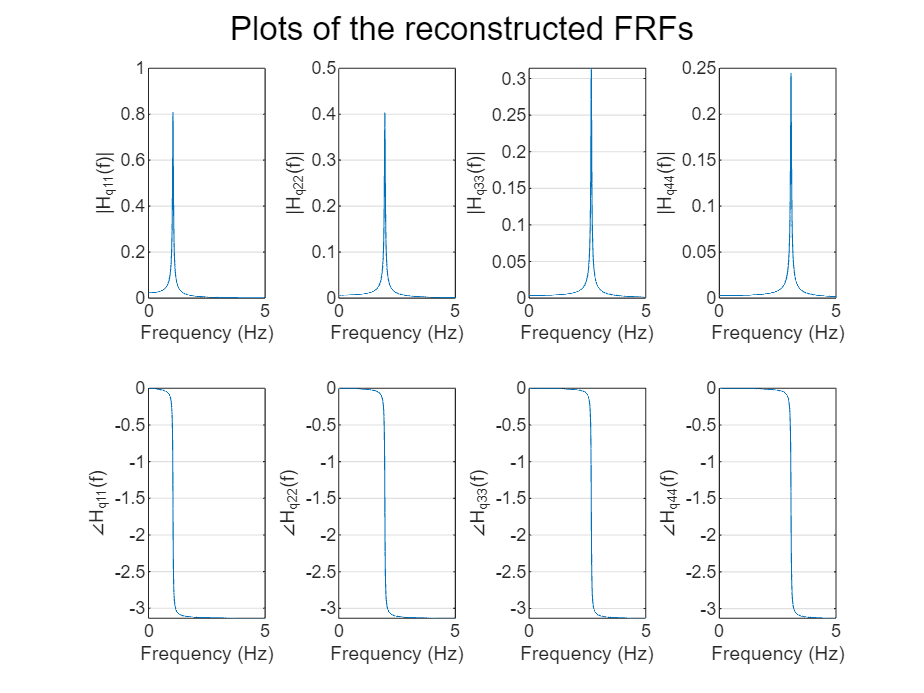

f_vals = linspace(0,5,1e3);

figure();
sgtitle('Plots of the reconstructed FRFs');
for i = 1:4
    % Evaluate the first element of FRFs at the given frequency values
    FRF_i = subs(FRFs(i), f, f_vals);

    % Plot the magnitude
    subplot(2,4,i)
    plot(f_vals, abs(FRF_i));
    xlabel("Frequency (Hz)"); 
    ylabel("|H_q_"+num2str(i)+"_"+num2str(i)+"(f)|");
    grid on;
    
    %
    % Plot the phase
    subplot(2,4,i+4)
    plot(f_vals, angle(FRF_i));
    xlabel('Frequency (Hz)');
    ylabel("\angleH_q_"+num2str(i)+"_"+num2str(i)+"(f)");
    grid on;
   
end